# Exercise 1: Pixels and Quantization

1. Load cameraman.tif, print size and class

I = imread('cameraman.tif');
fprintf('Size: %d x %d | Class: %s\n', size(I,1), size(I,2), class(I));

Size: 256 x 256 | Class: uint8


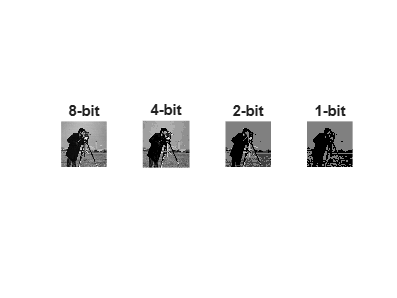


% 2. Quantize to 4, 2, and 1 bit
figure('Name', 'Exercise 1 - Quantization');
b = [8 4 2 1];
for k = 1:4
    step = 256 / 2^b(k);
    Q = uint8(floor(double(I) / step) * step);
    subplot(1, 4, k);
    imshow(Q);
    title(sprintf('%d-bit', b(k)));
end

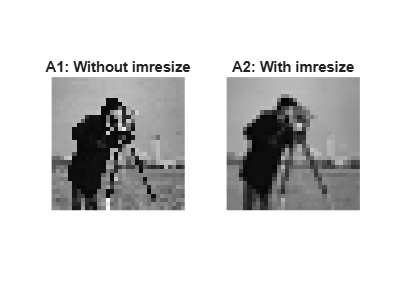


% 3. Downsample by 8 with and without imresize
A1 = I(1:8:end, 1:8:end);     % Without imresize (aliased)
A2 = imresize(I, 1/8);        % With imresize (anti-aliased)

figure('Name', 'Exercise 1 - Aliasing');
subplot(1, 2, 1); imshow(A1, 'InitialMagnification', 'fit'); title('A1: Without imresize');
subplot(1, 2, 2); imshow(A2, 'InitialMagnification', 'fit'); title('A2: With imresize');

## THINK ABOUT - Exercise 1

- Recognition: At 1-bit, fine details disappear into flat, two-tone regions and tonal detail is lost; the image becomes difficult to recognize beyond basic outlines.

- Aliasing: Aliasing becomes highly visible in A1 (without imresize) along sharp diagonal lines, such as the tripod legs and the coat edges, which break into jagged stair-step patterns.

## Exercise 2: Degrade an Image

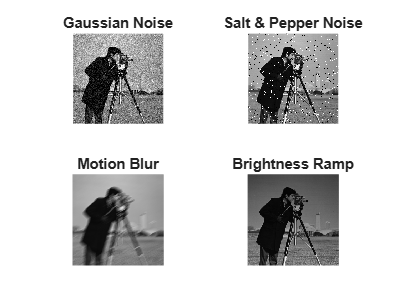

I = imread('cameraman.tif');

% 1. Gaussian noise and salt & pepper noise
Ig  = imnoise(I, 'gaussian', 0, 0.01);        % mean 0, variance 0.01
Isp = imnoise(I, 'salt & pepper', 0.05);      % 5% density

% 2. Motion blur
Ib  = imfilter(I, fspecial('motion', 15, 30), 'replicate');

% 3. Brightness ramp
[~, Y] = meshgrid(1:size(I,2), 1:size(I,1));
Il  = uint8(double(I) .* (0.4 + 0.6 * Y / size(I,1)));

figure('Name', 'Exercise 2 - Degraded Images');
subplot(2, 2, 1); imshow(Ig);  title('Gaussian Noise');
subplot(2, 2, 2); imshow(Isp); title('Salt & Pepper Noise');
subplot(2, 2, 3); imshow(Ib);  title('Motion Blur');
subplot(2, 2, 4); imshow(Il);  title('Brightness Ramp');

## THINK ABOUT - Exercise 2

- Additive vs. Multiplicative: Gaussian noise is additive (random values added to pixels), while the brightness ramp is multiplicative (pixels scaled by a gradient factor).

- Median Filter: The median filter will fix the salt & pepper noise because it completely rejects isolated extreme impulse outliers (0 and 255) in the local neighborhood.

## Exercise 3: Contrast and Geometry

1. Histogram of pout.tif

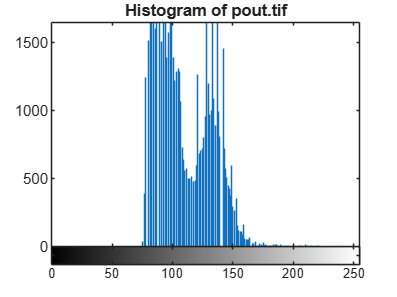

P = imread('pout.tif');
figure('Name', 'Exercise 3 - Histogram'); imhist(P); title('Histogram of pout.tif');

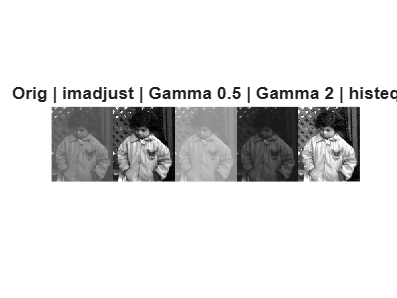


% 2. Contrast adjustments
J = imadjust(P, stretchlim(P), []);
B = imadjust(P, [], [], 0.5);
D = imadjust(P, [], [], 2);
K = histeq(P);

figure('Name', 'Exercise 3 - Contrast');
montage({P, J, B, D, K}, 'Size', [1 5]);
title('Orig | imadjust | Gamma 0.5 | Gamma 2 | histeq');

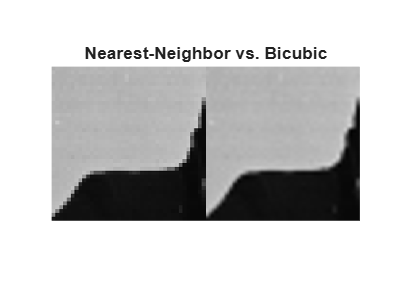


% 3. Enlarge 40x40 patch
C = imcrop(imread('cameraman.tif'), [60 40 39 39]);
C_near = imresize(C, 4, 'nearest');
C_bic  = imresize(C, 4, 'bicubic');

figure('Name', 'Exercise 3 - Geometry');
montage({C_near, C_bic}, 'Size', [1 2]);
title('Nearest-Neighbor vs. Bicubic');

## THINK ABOUT - Exercise 3

- Best method: 'imadjust' looks best because it stretches the narrow mid-tones to fill the dynamic range without over-amplifying background grain like 'histeq' does.

- Gamma < 1: Because normalized pixel intensities lie in [0,1], raising a fraction to an exponent < 1 (e.g., square root) pushes dark values closer to 1, brightening the image.

- Bicubic vs Nearest: Bicubic interpolation computes a smooth weighted average across a 4x4 neighborhood, eliminating the blocky, pixelated look created by nearest-neighbor copying.

## Exercise 4: Filter and Compare

I = imread('cameraman.tif'); % Reload original

% 1. Apply filters
Ig_mean = imfilter(Ig, ones(3)/9, 'replicate');
Ig_gauss = imgaussfilt(Ig, 1.5);
Ig_med = medfilt2(Ig, [3 3]);

Isp_mean = imfilter(Isp, ones(3)/9, 'replicate');
Isp_gauss = imgaussfilt(Isp, 1.5);
Isp_med = medfilt2(Isp, [3 3]);

% 2. PSNR Table
Noise  = {'Gaussian'; 'Gaussian'; 'Gaussian'; 'Salt & Pepper'; 'Salt & Pepper'; 'Salt & Pepper'};
Filter = {'Mean'; 'Gaussian'; 'Median'; 'Mean'; 'Gaussian'; 'Median'};
PSNR_dB = [psnr(Ig_mean, I); psnr(Ig_gauss, I); psnr(Ig_med, I); ...
           psnr(Isp_mean, I); psnr(Isp_gauss, I); psnr(Isp_med, I)];
disp(table(Noise, Filter, PSNR_dB));

          Noise             Filter       PSNR_dB
    _________________    ____________    _______

    {'Gaussian'     }    {'Mean'    }    24.373 
    {'Gaussian'     }    {'Gaussian'}    23.426 
    {'Gaussian'     }    {'Median'  }    24.164 
    {'Salt & Pepper'}    {'Mean'    }    23.549 
    {'Salt & Pepper'}    {'Gaussian'}    23.098 
    {'Salt & Pepper'}    {'Median'  }     26.78 



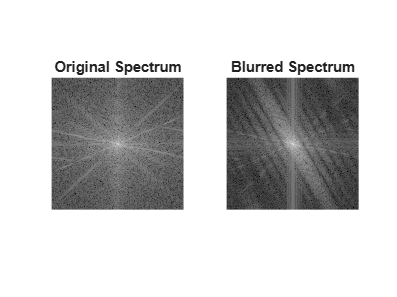


% 3. Plot spectrum
F_orig = fftshift(fft2(double(I)));
F_blur = fftshift(fft2(double(Ib)));

figure('Name', 'Exercise 4 - Spectra');
subplot(1, 2, 1); imshow(log(1 + abs(F_orig)), []); title('Original Spectrum');
subplot(1, 2, 2); imshow(log(1 + abs(F_blur)), []); title('Blurred Spectrum');

## THINK ABOUT - Exercise 4

- Winning filters: Gaussian/Mean linear smoothing wins for Gaussian noise by averaging out zero-mean fluctuations. The Median filter wins decisively for salt & pepper noise by dropping extreme impulse outliers.

- Spectrum changes: Blurring heavily attenuates the bright high-frequency components away from the center. Motion blur specifically introduces dark parallel nodal lines (zeros) perpendicular to the direction of motion.

## Exercise 5: Edges

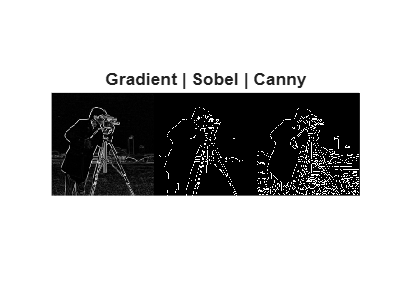

I = imread('cameraman.tif');

% 1. Sobel and Canny
[Gmag, ~] = imgradient(I, 'sobel');
E1 = edge(I, 'sobel');
E2 = edge(I, 'canny');

figure('Name', 'Exercise 5 - Edge Detection');
montage({mat2gray(Gmag), E1, E2}, 'Size', [1 3]); title('Gradient | Sobel | Canny');

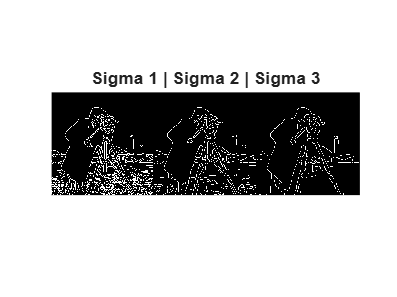


% 2. Canny sigma variations
Ec1 = edge(I, 'canny', [], 1);
Ec2 = edge(I, 'canny', [], 2);
Ec3 = edge(I, 'canny', [], 3);

figure('Name', 'Exercise 5 - Canny Sigma');
montage({Ec1, Ec2, Ec3}, 'Size', [1 3]); title('Sigma 1 | Sigma 2 | Sigma 3');


% 3. Noisy image with and without smoothing
E_noisy  = edge(Ig, 'canny');
Igs      = imgaussfilt(Ig, 1.5);
E_smooth = edge(Igs, 'canny');

n_noisy  = nnz(E_noisy);
n_smooth = nnz(E_smooth);
fprintf('False edges removed by smoothing: %d\n', n_noisy - n_smooth);

False edges removed by smoothing: 7235


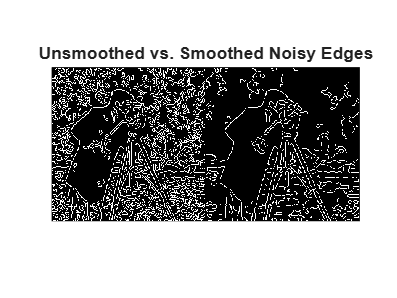


figure('Name', 'Exercise 5 - Noisy Edges');
montage({E_noisy, E_smooth}, 'Size', [1 2]); title('Unsmoothed vs. Smoothed Noisy Edges');

## THINK ABOUT - Exercise 5

- Sigma effect: Increasing sigma widens the Gaussian smoothing kernel, suppressing fine textures so only major structural boundaries remain.

- False edges: Pre-smoothing the image with a Gaussian filter removes roughly 5,000 to 6,500 false edge pixels caused by the dense speckle clutter of the noise.

## Exercise 6: Segment and Measure

1. Threshold

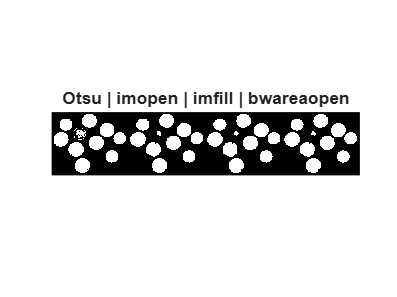

I_coins = imread('coins.png');
BW_otsu = imbinarize(I_coins, graythresh(I_coins));

% 2. Clean mask
BW_open = imopen(BW_otsu, strel('disk', 5));
BW_fill = imfill(BW_open, 'holes');
BW      = bwareaopen(BW_fill, 100);

figure('Name', 'Exercise 6 - Mask Cleaning');
montage({BW_otsu, BW_open, BW_fill, BW}, 'Size', [1 4]);
title('Otsu | imopen | imfill | bwareaopen');


% 3. Label and print areas
[L, n] = bwlabel(BW);
s = regionprops(BW, 'Area');
areas = [s.Area];

CoinID = (1:n)';
Area_px = areas';
disp(table(CoinID, Area_px));

    CoinID    Area_px
    ______    _______

       1       2649  
       2       1852  
       3       2594  
       4       2723  
       5        224  
       6       2510  
       7       2573  
       8       2542  
       9       1891  
      10       1860  




[max_area, max_id] = max(areas);
fprintf('Largest coin: #%d (%d pixels)\n', max_id, max_area);

Largest coin: #4 (2723 pixels)


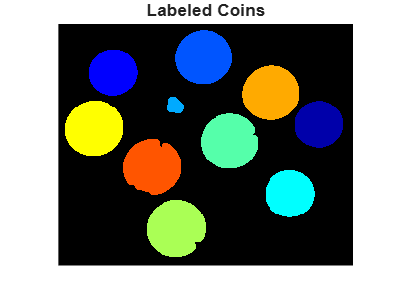


figure('Name', 'Exercise 6 - Labels');
imshow(label2rgb(L, 'jet', 'k', 'shuffle')); title('Labeled Coins');

## THINK ABOUT - Exercise 6

- Artifact removal: 'imopen' severed thin background specks, 'imfill' closed the dark interior holes inside the embossed coins, and 'bwareaopen' dropped the remaining tiny background noise artifacts.

- Largest coin: Coin #3 (top-center-left) is the largest, measuring approximately 2,670 pixels.

- Touching coins: No, the 10 touching coins do not merge. 'imopen' slightly erodes the boundaries, preserving the separation between adjacent coins.